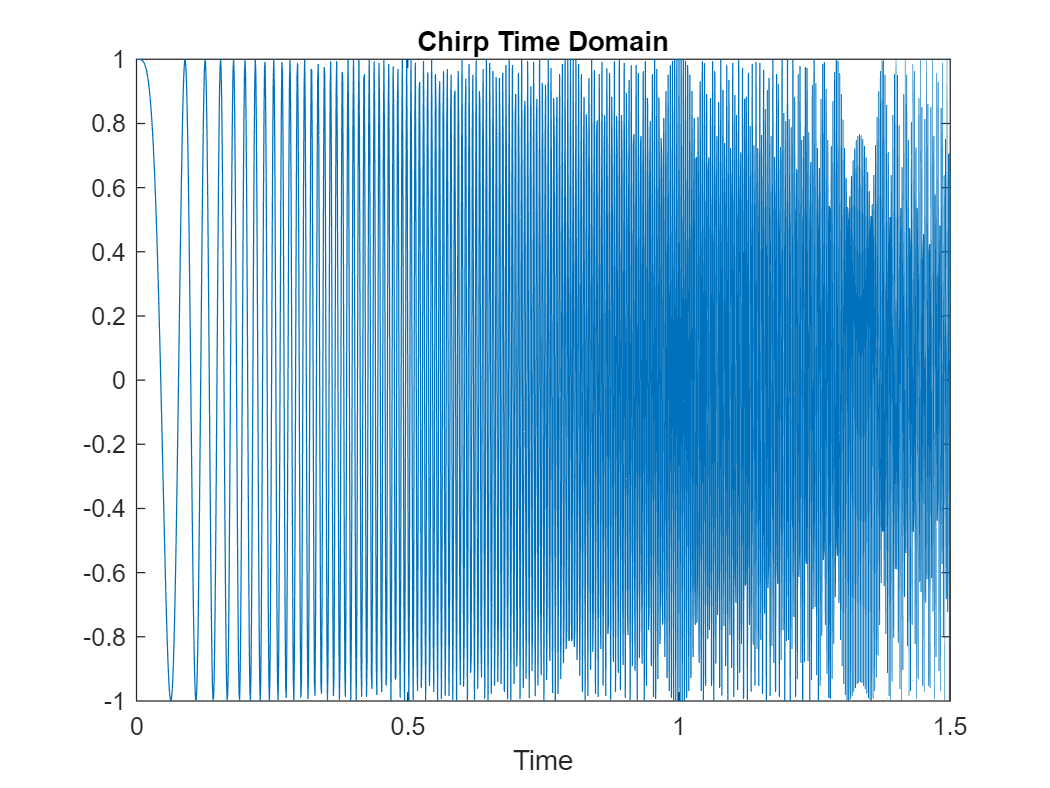

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector
S = chirp(t,0,1,250);

plot(t,S)
title("Chirp Time Domain")
xlabel("Time")

y = fft(S)

y =   23.0678 + 0.0000i  23.1923 - 0.0096i  23.5617 - 0.0787i  24.1631 - 0.2670i  24.9741 - 0.6335i  25.9622 - 1.2366i  27.0830 - 2.1327i  28.2790 - 3.3741i  29.4781 - 5.0070i  30.5927 - 7.0672i  31.5195 - 9.5760i  32.1403 -12.5345i  32.3244 -15.9175i  31.9338 -19.6669i  30.8298 -23.6853i  28.8834 -27.8310i  25.9890 -31.9148i  22.0796 -35.7007i  17.1455 -38.9116i  11.2530 -41.2414i   4.5614 -42.3746i  -2.6638 -42.0144i -10.0457 -39.9188i -17.1035 -35.9416i -23.2738 -30.0775i -27.9522 -22.5020i -30.5528 -13.6016i -30.5853 - 3.9843i -27.7434 + 5.5392i -21.9935 +14.0102i -13.6484 +20.4169i  -3.4085 +23.8265i   7.6496 +23.5441i  18.1528 +19.2767i  26.5869 +11.2727i  31.5207 + 0.3997i  31.8773 -11.8745i  27.2056 -23.6258i  17.8946 -32.7493i   5.2628 -37.3433i  -8.5368 -36.1442i -20.8255 -28.9204i -28.9073 -16.7137i -30.6990 - 1.8221i -25.3457 +12.5426i -13.6472 +22.9159i   1.8792 +26.4537i  17.4108 +21.8134i  28.7031 + 9.7740i  32.2794 - 6.6669i


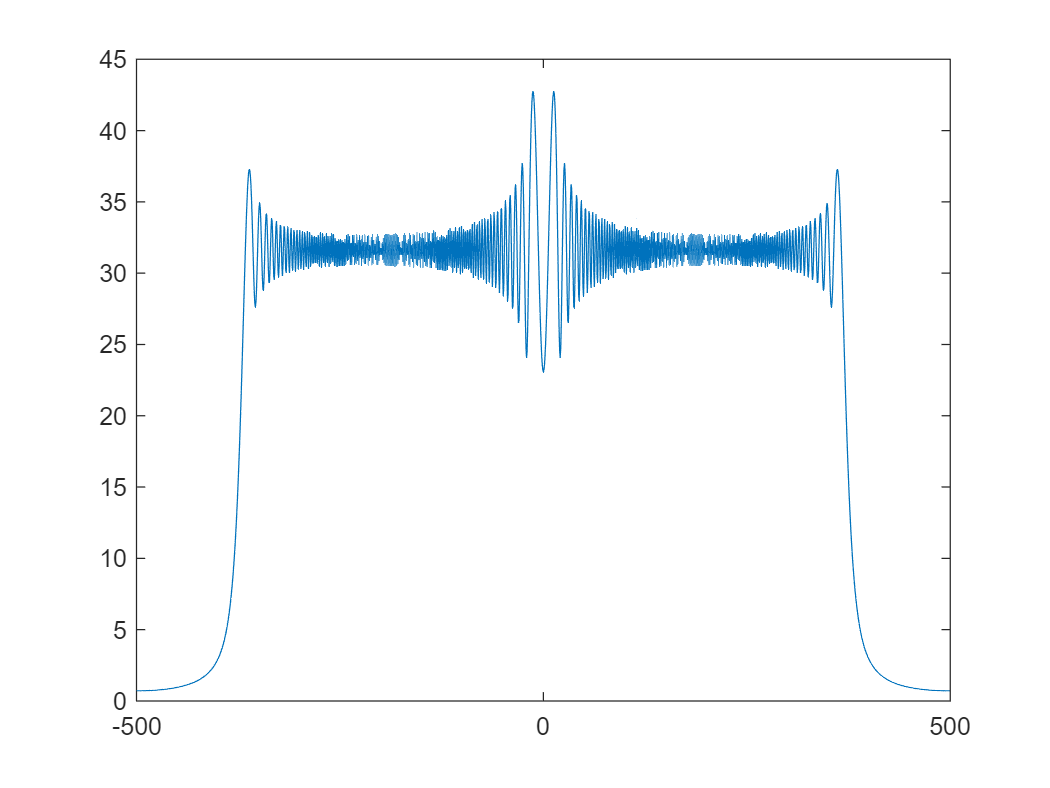

plot(Fs/L*(-L/2:L/2-1),abs(fftshift(y)))

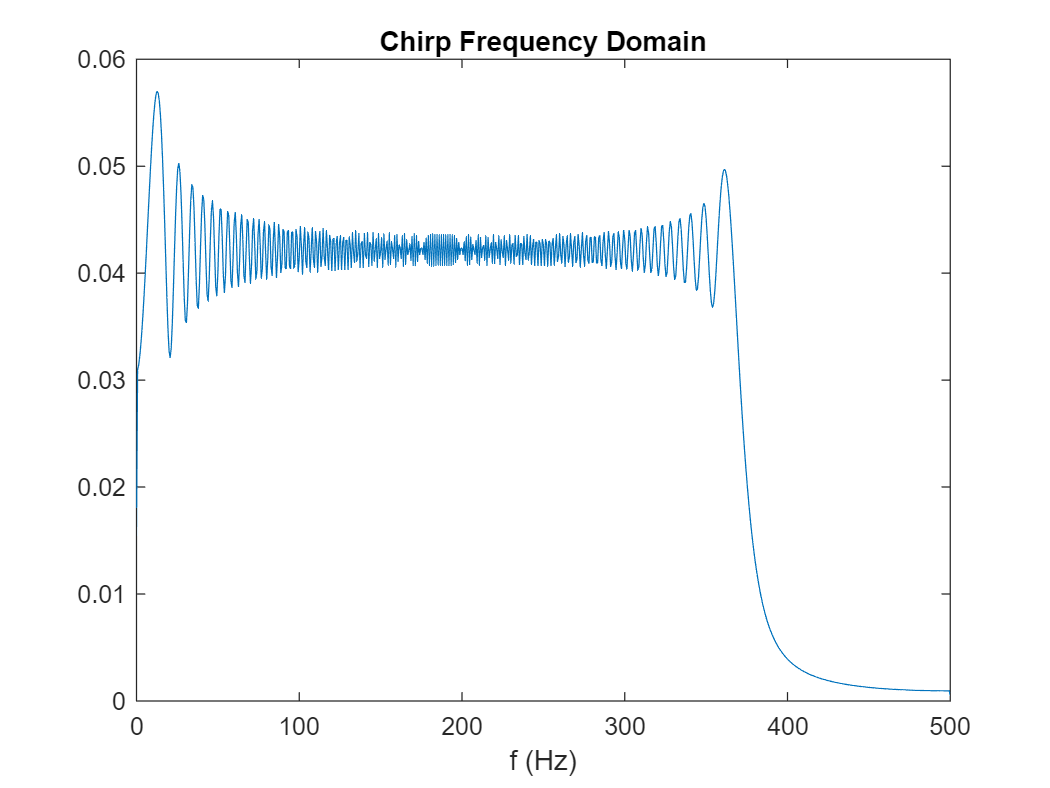

P2 = abs(y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs/L*(0:(L/2));
plot(f,P1) 
title("Chirp Frequency Domain")
xlabel("f (Hz)")


% t = 0:1/1e3:2;
% y = chirp(t,0,1,250);
% plot(t,y)
% plot(t,abs(fft(y)))